# Test Controllers

clear
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

#### Load DGU Network parameters from file and initialize the class for the DGU Network

- Constant variables for the rest of the analysis:

clear
length_sim = 35;
simStart = 1;
utils = utilityFunctions; % utility function class
sim = SimFunctionsPnP; % simulation function class
filename = 'config_DGU_1.txt'; % Initial DGU Network
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0



activeDGU = 1:nb_subsystems; % all DGU are active

#### Define the resistor values connecting the DGUs i.e. interconnection strengths.

Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8;

Make the interconnection between DGU 3 and DGU 6 variable:

Rij_mat(3,6) =0.8

Rij_mat =          0    1.7500         0         0         0         0
         0         0    3.5000    1.7500         0         0
         0         0         0         0    2.8000    0.8000
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


Rij_mat = Rij_mat + tril(Rij_mat',1); % symmetric matrix for undirected graph
%% Instantiate DGU NETWORK
dguNet = DGU_network(nb_subsystems);
dguNet = dguNet.setConnectionsGraph(Rij_mat);
dguNet = dguNet.setActiveDGU(activeDGU);

- Plot the Graph describing the Network

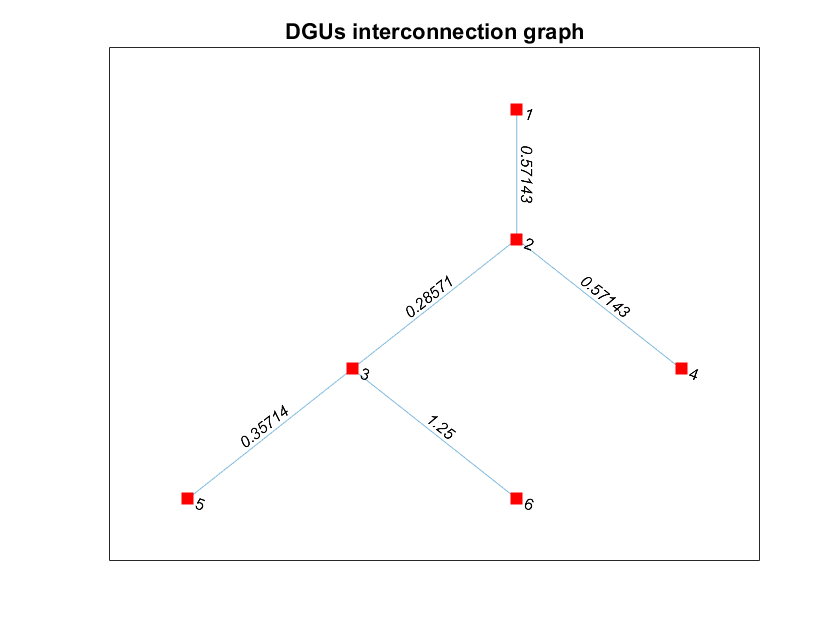

plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("DGUs interconnection graph")

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.95, 50.2, nb_subsystems); % references
Il = linspace(2.5, 7.5, nb_subsystems);
% set Electrical parameters
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end
dguNet = dguNet.initDynamics();

#### Test the Passivity controller, $\Delta$ Formulation of constraints to converge to references

delta_config = true; % Delta-Formulation of DGU Network
dguNet = dguNet.compute_Ref_Constraints(delta_config); % constraints in delta formulation
control_type = "PASSIVITY";
config = "DISTRIBUTED";
dguNet = sim.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612



ans = "K3"

   -0.4021   -0.1549



ans = "P3"

    8.3946    0.6205
    0.6205    0.3201



ans = "K4"

   -0.0062   -0.0945



ans = "P4"

    4.1335    0.6268
    0.6268    5.5436



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6916
    4.6916    1.6810



ans = "K6"

   -0.0567   -0.0992



ans = "P6"

    5.2750    0.7658
    0.7658    1.7112



[x0, ~, ~, ~] = utils.tuningParam(dguNet, delta_config) % initial parameters definition

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


[X,U] = sim.sim_DGU_distributed(x0, length_sim, dguNet, dguNet.Ki);
error_pass = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_pass = 5.1450

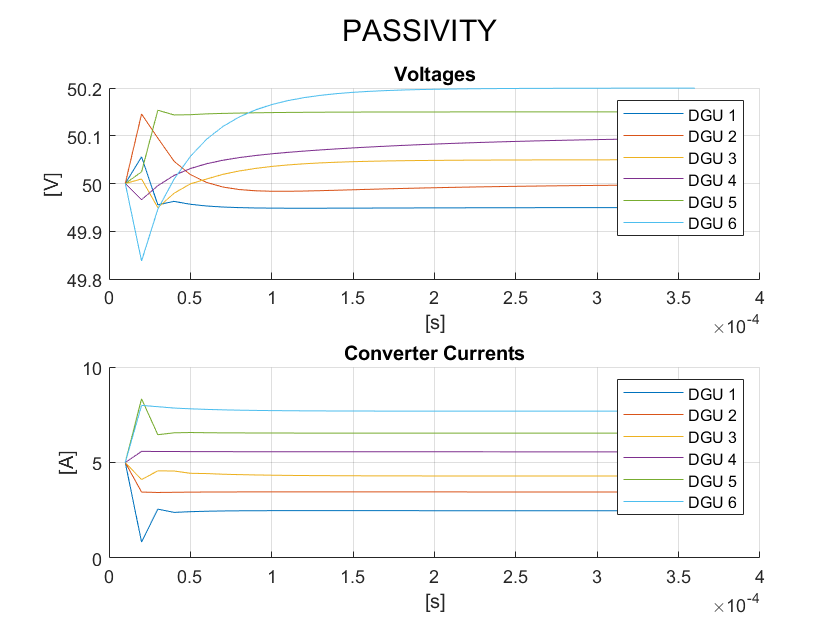

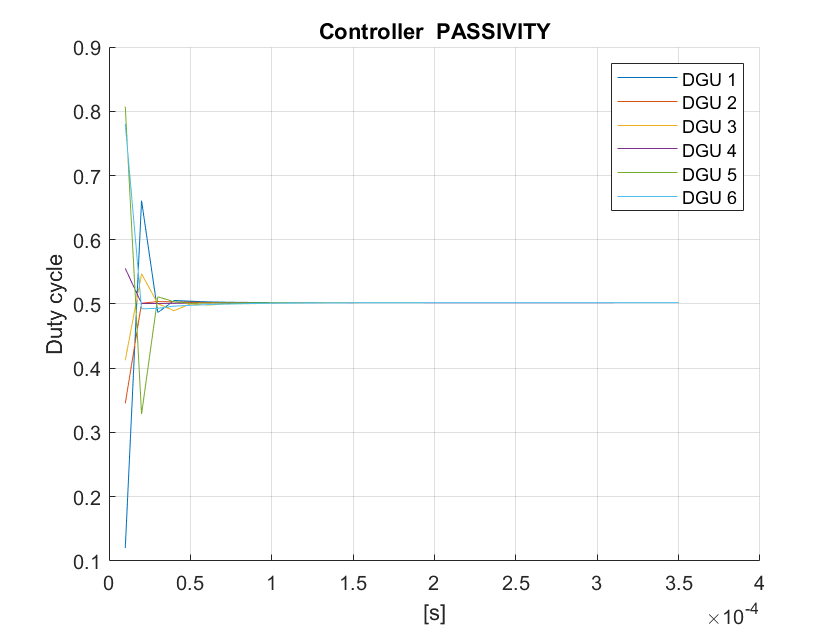

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart,activeDGU);

#### Evaluate Passivity controller by comparing it to LQR

config = "GENERAL";
control_type = 'LQR';
Ad = dguNet.global_sysd.A; Bd = dguNet.global_sysd.B; 
Q = eye(size(Ad,1)); R = eye(size(Bd,2));
disp("LQR controller Gain");

LQR controller Gain


[Klqr, Pinf, ~] = dlqr(Ad, Bd, Q,R)

Klqr =     0.0758    0.0966   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0821    0.1097   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0812    0.1067    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0765    0.0997    0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0753    0.0970    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0765    0.0997


Pinf =     8.4984    0.5075   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5075    1.0428   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000    6.0006    0.5093   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.5093    1.0622   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0000    6.6002    0.5089    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.5089    1.0562    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    7.1987    0.5078   -0.0000   -0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.5078    1.0504    0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000    0

[Xlqr,Ulqr] = sim.sim_global_DGU(x0, length_sim, dguNet, -Klqr);
error_lqr = utils.tracking_error(Xlqr,Ulqr,config,dguNet,activeDGU)

error_lqr = 4.6486

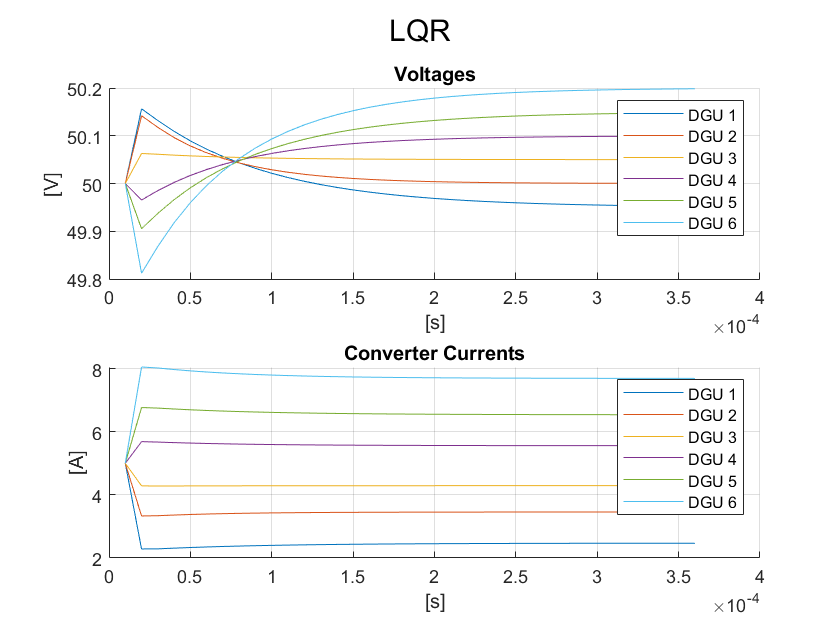

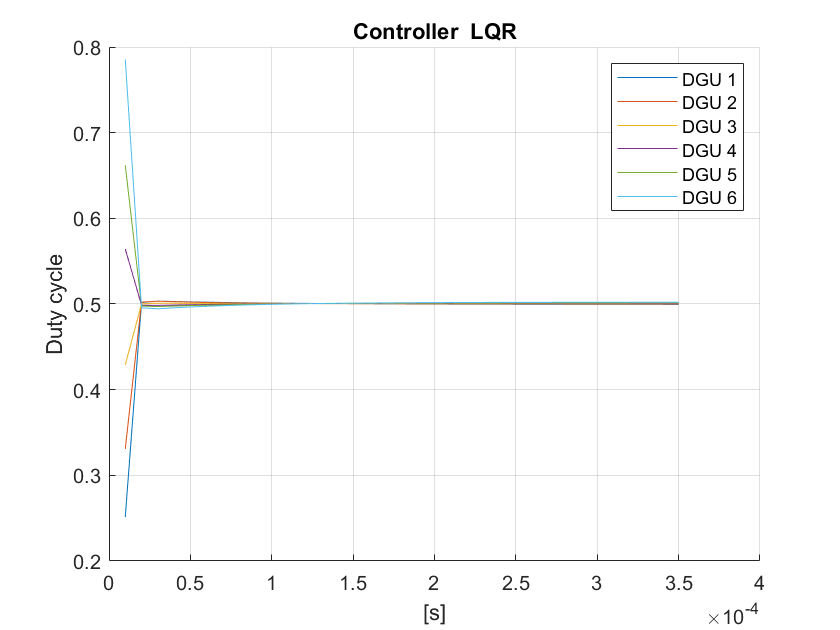

dguNet.plot_DGU_system(Xlqr,Ulqr, config, control_type, dguNet, simStart, activeDGU)

- Compute the suboptimality index $\frac{e_{pbc} - e_{lqr}}{e_{lqr}}$  where the tracking error is defined as:

$e=\sqrt{\sum_{k=0}^{T} \sum_{i=1}^{6}\left(\Delta V_{i}^{k^{2}}+\Delta I_{i}^{k^{2}}+\Delta u_{i}^{k^{2}}\right)}$ is computed where $\Delta V_{i}^{k}=V_{i}^{k}-V_{r_{i}}, \Delta I_{i}^{k}=I_{i}^{k}-I_{r_{i}}$, $\Delta u_{i}^{k}=u_{i}^{k}-u_{r_{i}}, T$ is the simulation time, $I_{r_{i}}$ and $u_{r_{i}}$ are the steady state values of the corresponding variables. 

suboptimality_index = (error_pass - error_lqr)/error_lqr

suboptimality_index = 0.1068

- Compare cost of the 2 methods

sprintf("Cost using the passive controller = %d", utils.compute_QR_cost(X,U,Q,R,"DISTRIBUTED", dguNet.Xref , dguNet.Uref))

ans = "Cost using the passive controller = 2.647057e+01"

sprintf("Cost using the LQR controller = %d", utils.compute_QR_cost(Xlqr,Ulqr,Q,R,"GENERAL",dguNet.Xref , dguNet.Uref))

ans = "Cost using the LQR controller = 2.160954e+01"

For the LQR controller, the cost can also be computed as $J_\infty = x_0^T P_\infty x_0$

dx0 = vertcat(x0{:}) - vertcat(dguNet.Xref{:});
sprintf("Cost of LQR controller using closed form solution = %d", dx0'*Pinf*dx0)

ans = "Cost of LQR controller using closed form solution = 2.160963e+01"

#### Test MPC without reconfigurable terminal ingredients (also $\Delta$ Formulation)

$\mathbb{X}_f^i = \{ x_i \in \mathbb{R}^m |  V_f^i(x_i) \leq \alpha_i\}$ where $V_f^i(x_i) = x_i^T P_i x_i$ and $\alpha_i^+ = \alpha_i + x_{Ni}^T(N) \Gamma_i 
 x_{Ni} (N)$

- **Using Lyapunov terminal constraints to get **$\alpha_i$

delta_config = true;
[x0, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config)

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Q_Ni = 1×6 cell array
    {4×4 double}    {8×8 double}    {8×8 double}    {4×4 double}    {4×4 double}    {4×4 double}


Ri = 1×6 cell array
    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}


dguNet = dguNet.compute_Ref_Constraints(delta_config); % constraints in delta formulation

Set passivity boolean to false

use_passivity = false; 

Compute $P_i$, $\Gamma_i$, $\alpha_i$

[P, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet, ...
                                                  use_passivity);

ans = "Local feedback control laws K_N6"

    0.0010    0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591    0.0000         0         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615         0         0         0



ans = "Local feedback control laws K_N3"

    0.0003    0.0000         0         0    0.0003         0    0.0011         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724   -0.0000         0         0    0.2862   -0.0000    0.5724    0.0000



ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



sprintf("Initial terminal set constrait alpha = %d", alpha_i)

ans = "Initial terminal set constrait alpha = 1.369458e-01"

alpha = alpha_i*ones(nb_subsystems,1); % same alpha for every subsystem @ beginning
control_type = "MPC with offline computation of terminal ingredients";
config = "DISTRIBUTED";

Simulate system with online MPC and $\alpha_i$ update outside of the MPC

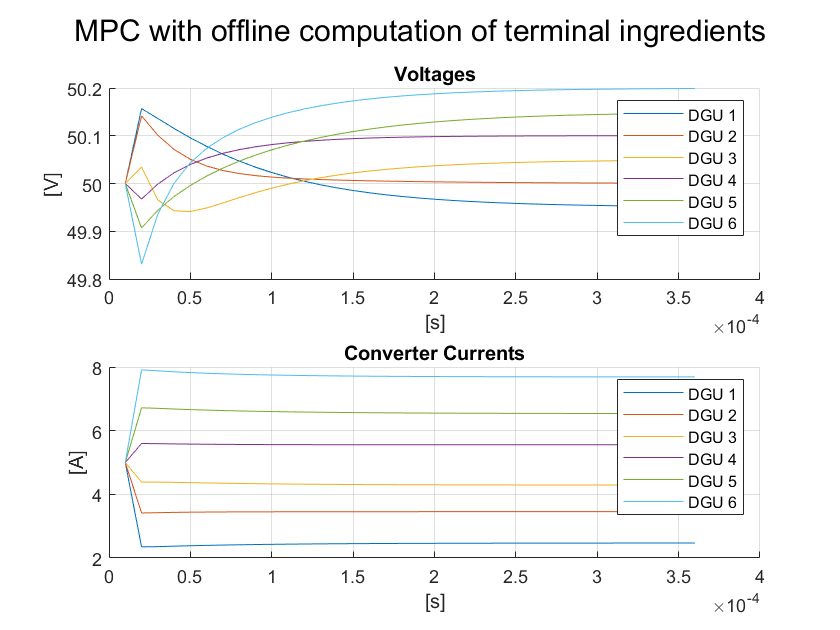

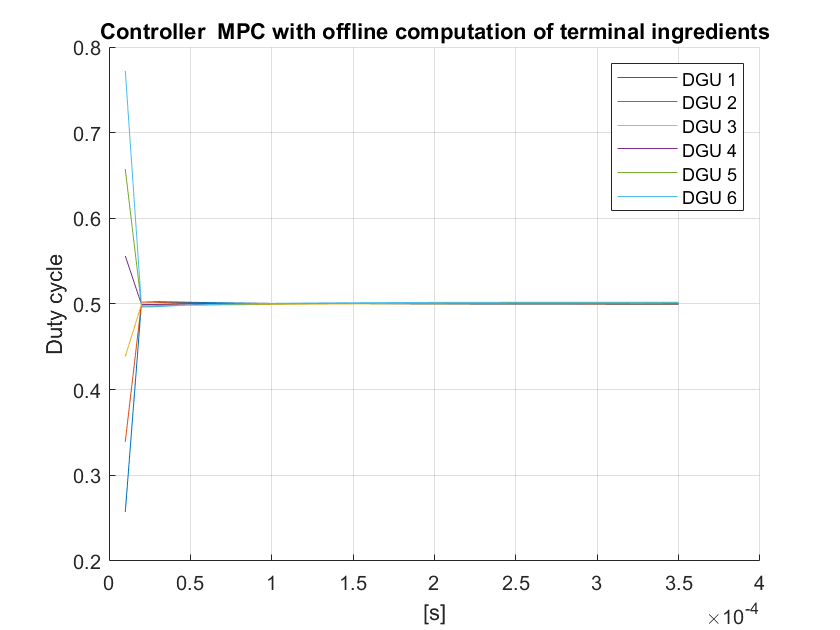

[X,U] = sim.mpc_sim_DGU_delta(@mpc_online, x0, length_sim, dguNet,...
                         alpha, Q_Ni, Ri, P, Gamma_Ni);
dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, activeDGU)

- Compute the tracking error for the online distributed MPC with offline distributed initial terminal set synthesis

error_mpc_1 = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_mpc_1 = 4.5603

            2.   ** Using Passivity to obtain **$P_i$ and $\alpha_i$: 

$\alpha_i$ is only computed here in the interest of comparing the size to the previous implementation, as the offline LP problem for a decentralized Terminal Set Synthesis only involves the gain $K_i$ and $P_i$ matrices. The online distributed MPC with $\alpha_i$ update is not implemented, as the $\Gamma_i$ from the passivity optimization problem represents the dissipation rate matrix and has therefore another meaning than in the *Distributed synthesis and control of constrained linear system *Paper*.*

use_passivity = true;
[P, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet, ...
                                                  use_passivity);

ans = "passivity gain of system 1 is"

   -0.6387   -0.1384



ans = "passivity gain of system 2 is"

   -0.0103   -0.1017



ans = "passivity gain of system 3 is"

   -0.4021   -0.1549



ans = "passivity gain of system 4 is"

   -0.0062   -0.0945



ans = "passivity gain of system 5 is"

   -0.6108   -0.1390



ans = "passivity gain of system 6 is"

   -0.0567   -0.0992



sprintf("Initial terminal set constrait alpha = %d", alpha_i)

ans = "Initial terminal set constrait alpha = 1.591473e-03"

#### Test MPC for reference tracking with reconfigurable terminal ingredients (online)

Not in $\Delta$ Formulation

delta_config = false;
dguNet = dguNet.compute_Ref_Constraints(delta_config);

Obtain $K_i$ and $P_i$ from passivity, terminal set constraints directly implemented in the MPC

dguNet = sim.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612



ans = "K3"

   -0.4021   -0.1549



ans = "P3"

    8.3946    0.6205
    0.6205    0.3201



ans = "K4"

   -0.0062   -0.0945



ans = "P4"

    4.1335    0.6268
    0.6268    5.5436



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6916
    4.6916    1.6810



ans = "K6"

   -0.0567   -0.0992



ans = "P6"

    5.2750    0.7658
    0.7658    1.7112



config = "DISTRIBUTED";
control_type = "MPC with terminal ingredients online computation";
[x0, Q_Ni, Ri, ~] = utils.tuningParam(dguNet, delta_config)

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Q_Ni = 1×6 cell array
    {4×4 double}    {8×8 double}    {8×8 double}    {4×4 double}    {4×4 double}    {4×4 double}


Ri = 1×6 cell array
    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}


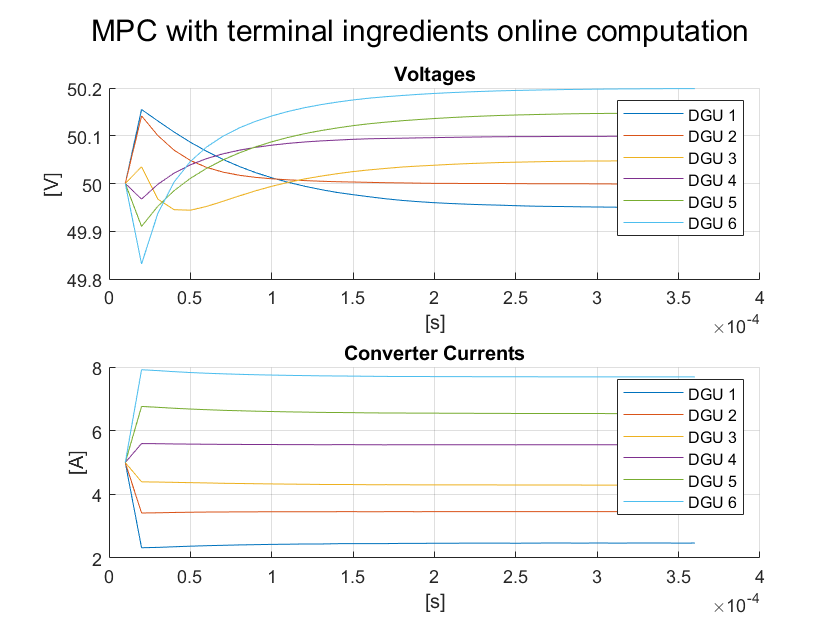

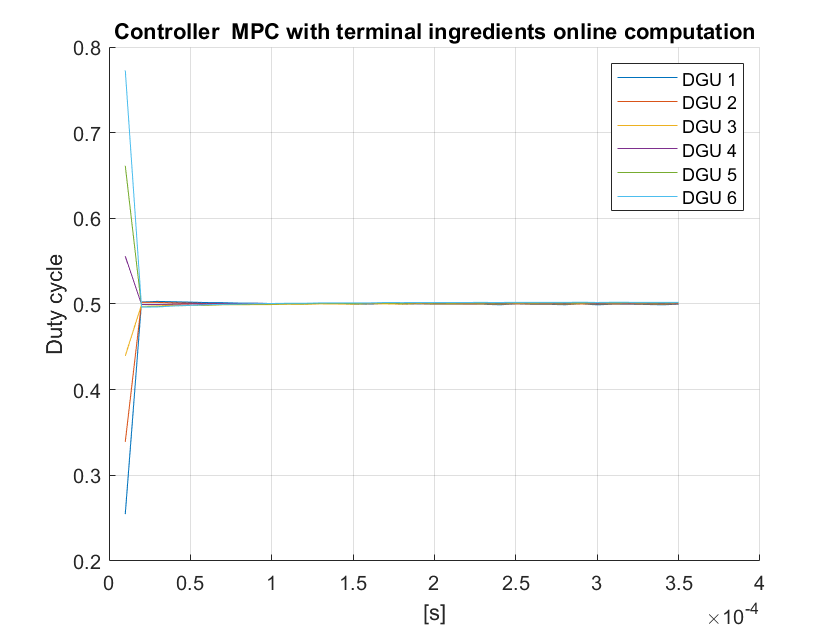

[X,U] = sim.mpc_DGU_tracking(@mpc_online_2, x0, length_sim, dguNet, Q_Ni, Ri);
dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart,activeDGU); % plot results

- Compute the tracking error for the online MPC with reconfigurable terminal ingredients

error_mpc_2 = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_mpc_2 = 4.5604